# Example 1: Least Squares Fitting

In this example we will fit a Gaussian function using the Least Squares Method on Gaussian generated data stored in *gaus1.txt* that can be found in the data directory. As a reminder, the Least Squared Method minimizes the differences between the data points and the model values using,


$$\frac{\partial}{\partial a_{j}}\sum_{i = 1}^N (y_{i} -f(x_i|\sigma, \bar{x},A))^2 = 0$$


Where  $\bar{x}$ is the mean value, $\sigma
$ the standard deviation, and $A
$is the normalization constant or amplitude. Normal distributions, of this type, are commonplace in physics and scientific analysis. Being able to spot and extract information from these distributions is a crucial skill for scentists. Usually, we attempt to find the center location of the peak $\bar{x}$ (i.e. the mean value of an atomic spectral line) while using the standard $\sigma
$ to find the error on the mean. The individual errors on the points don't affect the fit as much in a Gaussian generated dataset. With that in mind, this first example will only use the least squares method which disregards the point's uncertainties. In the second example the uncertainties will be incorporated using the general $\chi^2
$-fitting method. 

## Read In Raw Data:

First create a path to the data folder,

data_path = 'data/';
file_name = 'gaus1.txt';                        
file_path = strcat(data_path, file_name);
data = dlmread(fullfile(data_path,file_name));    

Split the data into individual vectors for $x
$ and $y$ values

x_data = data (:, 1);
y_data = data (:, 2);

Sort the $x
$ and $y$ vectors in order of x_data. This ensures our data goes up in positive vaues in the $x
$ axis

[x_data, order] = sort(x_data);
y_data = y_data(order);

Plot the Raw data to see the gaussian shape of the dataset.

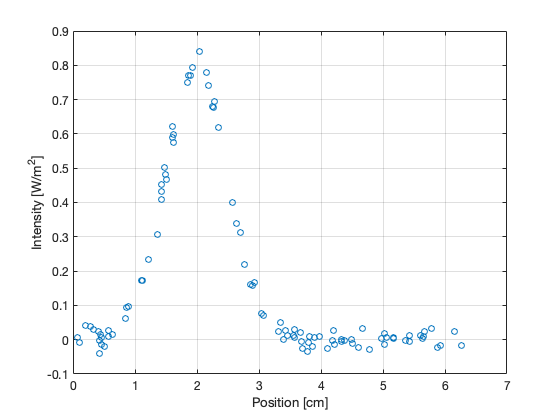

fig1 = figure;
ax1 = axes(fig1);
hold on
grid on
plot(ax1, x_data, y_data, 'o');
ax1.FontSize = 12;
ax1.Box = 'on';
xlabel(ax1, 'Position [cm]');
ylabel(ax1, 'Intensity [W/m^2]');

## Least Squares Fitting:

MATLAB is equipped with its own least squares implementation. This can be called using the *fit(xdata, ydata, fittype)* function, which takes in the data in x and y, as well as, a template of the model function we are attempting to fit. *fit()* has some generic models that can be defined by string keywords such as 'gauss1' and 'ploy1'. More can be found at [https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.](https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.) In this example we will use the 'gauss1' template and leave general fit types for later examples. The 'gaus1' fit type model uses a 3-parameter 1-Dimensional Gaussian,


$$f(x) = a_{1} \cdot \text{exp}(-((x - b_{1})/c_{1})^2)$$


Where $(a_{1}, b_{1},c_{1}) = (A, \bar{x},\sqrt{2}\sigma)$ are the parameters of the fit model (notice that $c_i$ is not exactly $\sigma$ in this definiton). The function will attempt to fit each of these parameters depending on the input data we feed it.

f = fit(x_data, y_data, 'gauss1')

f =      General model Gauss1:
     f(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =         0.8  (0.7874, 0.8126)
       b1 =       1.995  (1.986, 2.004)
       c1 =      0.7055  (0.6919, 0.719)

The above output shows the fit object 'f'. It varifies the model type and the final fit parameters and their confidence intervals (don't mistake these as the errors on our paramters, that will be delt with in the general $\chi^2
$-fitting). The fit function is now fully defined by $(a_{1}, b_{1},c_{1})$. So the next step would be to extract those values and plot the full function over our data.

First let's generate an array of x values that spans the x range of our data using *linspace().*

x = linspace(x_data(1), x_data(end), 1000);

Next we can construct the y values of our gaussian fit by apply the parameters to the gaussian equation and feed it the full x value array that we just generated. Keep in mind that when we call the fit parameters we need to reference the fit object 'f' (i.e. f.a1 will give us the $a_{1}$ value of the fit).

y = f.a1 * exp(-((x - f.b1)/f.c1).^2);

Now we're in a position where we can just plot the values of our fit over our exisiting plot of the raw data,

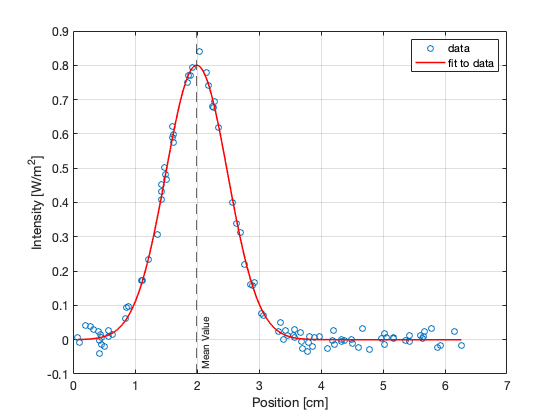

plot(x, y, 'r-', 'LineWidth',1.5)
x1 = xline(f.b1,'--','Mean Value');
x1.LabelVerticalAlignment = 'Bottom';
legend('data', 'fit to data')
hold off

The final step of your analysis would be to cast your final results in a meaningful format. In this case we can quote our mean value as our result with it's uncertainty (from the standard deviation).

Result: $\bar{x} \pm \sigma$ [cm]

fprintf('Our result is: %.2f +/- %.2f cm. ', f.b1, f.c1*sqrt(2) ) 

Our result is: 2.00 +/- 1.00 cm. 

# Example 2: Generalized $\chi^2$- Fitting & P-value Statistics

In example (1) we explained the process of fitting your model onto data using the least squared method. Now we'll be taking into account the error associated with our data. The example dataset we will be using is still gaus1*.txt*  but instead we have added errors to the y values. There may be additional microphysics effects that might affect our results, such as shifts and biases. In this case, we consider a general Gaussian with a shift factor $a_4$: $f(\theta| a_{1}, a_{2}, a_{3}, a_{4})$. Now that we have our model we can introduce the $\chi^2$ function,


$$\chi^2 = \sum_{i = 1}^N \frac{(y_{i}-f(x_{i}|a_{1},a_{2},...,a_{n}))^2}{\sigma_{i}^2} $$


Where  $y_{i}$ are the data points, $a_{i} 
$ the parameters of the model, and $\sigma_{i}$ the standard deviation on $y$. Similar to the least squares method, we minimize the function with respect to the paramters, $\partial \chi^2/\partial a_{j}  = 0$. You can easily notice that when $\sigma_{i} = 1$we recover the least squares minimization.

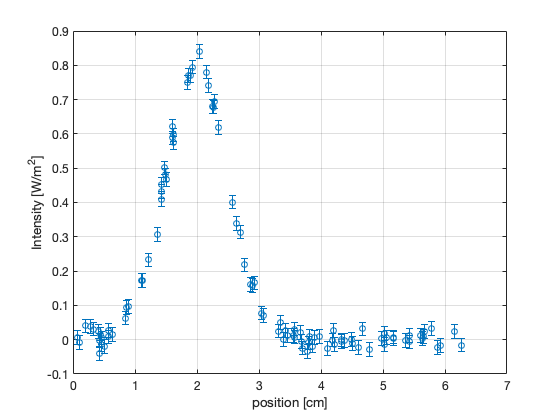

y_err = ones(size(y_data))*.02; % add errors as a faction of the y-data

fig2 = figure;
ax2 = axes(fig2);
hold on
grid on
errorbar(ax2, x_data, y_data, y_err, 'o');
ax2.FontSize = 12;
ax2.Box = 'on';
xlabel(ax2, 'position [cm]');
ylabel(ax2, 'Intensity [W/m^2]');

## $\chi^2$-Fitting and Error Analysis:

MATLAB's $\chi^2 $-fitting function is the same as it's least squared function *fit()* . In this case, we feed it an additional parameter, the 'weight'. The weight is defined as $w = 1/\sigma^2$. The reason being that this is the factor that appends to the original least squares method. Instead of using a generic model fit type found in [https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.](https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.) we're going to construct our own fit model using the *fittype() *function for a general four parameter Gaussian,


$$f(x| a_{1}, a_{2}, a_{3}, a_{4}) = a_{1} \cdot \text{exp}(-((x - a_{2})/a_{3})^2) + a_{4}$$


Here $a_1$ encodes the normalization, $a_2$ the mean, $a_3$ the standard diviation, and $a_4$ is a horizontal shift. Keep in mind that the MATLAB doesn't understand the underlying physics and is only concerned with numerical computations (This isn't true with symbolic languages). With that in mind, we should keep track of the units on each parameter. Since $f(x)$ has units of $[W/m^2]$ then, ($a_1$, $a_2$, $a_3$, $a_4$) have units of ($[W/m^2]$, $[\text{cm}]$,$[\text{cm}]$,$[W/m^2]$) respectivly. Setting up the fit type object,

ft = fittype('a1*exp(-((x - a2)/a3)^2) + a4');

Next, call the *fit() *function with the data, errors and fittype. Once the weights are given to the function it will return more than the ordinary fit object shown in example.1. This time it'll output an array of objects we'll call [*f, gof, fit_output*]. The first, '*f', *is the same object from LS fitting which carries the fittype model and fit paramters. We will discuss the others in the next section.  

[f, gof, fit_output] = fit(x_data, y_data, ft, 'Weights', y_err.^(-2),...
    'Startpoint', [2,1,+pi/4,-1]);
f    % Display the contents of the fit object (parameters) 

f =      General model:
     f(x) = a1*exp(-((x - a2)/a3)^2) + a4
     Coefficients (with 95% confidence bounds):
       a1 =      0.7989  (0.7858, 0.812)
       a2 =       1.995  (1.986, 2.004)
       a3 =     -0.7034  (-0.7184, -0.6885)
       a4 =    0.001599  (-0.003407, 0.006606)

Finding the errors on the parameters requires extra statistics and some linear algebra. Within the *fit_ouput *object matlab calculates the weighted Jocobian matrix $J$. This mathematical object facilitates the transformations from the parameter coordinate system into the new minimized system (you don't have to worry about understanding the gritty details if this is outside the scope of your statistics knowledge). We care about this object because it allows us to calculate the covariance matrix $\epsilon_{ij}$, which encodes the various uncertainties of our parameters. The covariance is defined as, 


$$\epsilon_{ij} = \frac{1}{2}\bigg(\frac{\partial \chi}{\partial a_{i} \partial a_{j}}\bigg)^{-1}  = (J^{T}J)^{-1}$$
 

The last line is the inverse of the product of the jocobian matrix with its transpose and can easily be done using the following expression,

J = fit_output.Jacobian;           %extract the jocobian matrix
covariance_matrix = inv(J'*J)

covariance_matrix = 	1.0e+-4 *

    0.4677    0.0213    0.2197   -0.0472
    0.0213    0.2191   -0.0482   -0.0054
    0.2197   -0.0482    0.6082    0.0854
   -0.0472   -0.0054    0.0854    0.0681


Diagonal entries of the covariance matrix correspond to the variances (or the square of the standard deviation $\sigma^2$) of the parameters, starting in order of how we defined the paramters ($a_1$, $a_2$, $a_3$, $a_4$). Whereas the off-diagonal terms are the covariances between two parameters, i.e. the (2,1)-term is Cov($a_{2}$,$a_{1}$). We can pick off the terms from the matrix and compute the errors: $\sigma_{a_1} = \sqrt{0.4677e-4} = 0.0068 W/m^2$, $\sigma_{a_1} = \sqrt{0.2191e-4} = 0.0047 \text{ cm}$, $\sigma_{a_1} = \sqrt{0.608e-4} = 0.0077 \text{ cm}$, $\sigma_{a_1} = \sqrt{0.0681e-4} =  0.0026W/m^2$

Let's visually inspect the goodness of fit by plotting the fitted function with the found parameters over the raw data. Later we can use more robust quantitative methods of goodness of fit with the remaining objects returned from *fit(). *First, let's generate an array of x values that spans the x range of our data using *linspace() * and the model fucntion.

x = linspace(x_data(1), x_data(end), 1000);
y = f.a1*exp(-((x - f.a2)/f.a3).^2) + f.a4;

Ploting the function over the already created (and held) figure objects.

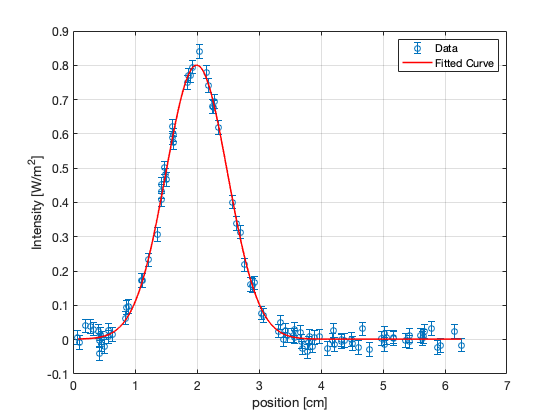

plot(x, y, 'r-', 'LineWidth',1.5)
legend(ax2, "Data", "Fitted Curve")

## Goodness-of-fit and P-value:

Visually the model seems to fit well over our data. Although, these types of visual inspections can be a dangerous form of inference because we'll show quantatively that the model doesn't fit our data well at all. The parameters we just found are taken at the minimum value of the $\chi^2$ function, which we call $\chi^2_{\text{min}}$. If we were to redo the experiment the recalculated $\chi^2_{\text{min}}$ values should follow the $\chi^2$distribution, hence the name, 


$$f(x|\nu) = \frac{1}{2^{2/\nu}\Gamma(\nu/2)}x^{\nu/2-1}e^{-x/2}$$


Where $\nu$ is the number of degrees of freedom, which is the number of data points - the number of model parameter,


$$\nu = \text{(no. data  points) - (no. params) = } 100 - 4 = 96$$


We can either brute force calculate $\chi^2_{\text{min}}$ using the $\chi^2$ function and our data or we can use the value already calculated in the *gof output.*

min_chi_2_brute = sum((y_data - f.a1*exp(-((x_data - f.a2)/f.a3).^2) ...
    - f.a4).^2 ./ y_err.^2)

min_chi_2_brute = 89.7175

min_chi_2 = gof.sse

min_chi_2 = 89.7175

ndof = gof.dfe;

Both methods prove to give the same result. It'll be easier to use the *gof.sse *value for future analysis. We are now in a position to ask: *"what is the probability, if our hypothesis is correct, of getting a *$\chi^2_{\text{min}}$* value greater than or equal to the one that we got?". *The answer is the p-value, and is given by, 


$$p = \int^{\infty}_{\chi^2_{\text{min}}} f(x|\nu) dx$$


This basically represents the integral of the remaining (one sided) tail $f(x|\nu)$. We can check if our p-value is less than some selected signifigance, usually taken to be 0.5 ($2\sigma$ signifigance). If p < 0.05, then we reject the hypothesis that our chosen model is the correct model. Otherwise, we fail to reject the hypothesis. That’s the strongest thing we can say; we are unable to conclude that the hypothesis is the correct one. But getting a large p-value (i.e. > 0.95) is also non-ideal. It means that we are overfitting the data (i.e. too many parameters in the fit model) or that our measurement uncertainties are overestimated. On average, we expect the p-value to be about 0.5 if the hypothesis is correct.

Alternatively, the chi-squared distribution has an expectation value of 𝜈, so if our calculated $\chi^2_{\text{min}}$ ≈ 𝜈, then we say the fit is ‘good’. Using this logic we it is customary to define $\chi^{2}_{\nu} =\chi^2/\nu $, the reduced chi-squared statistic. Based on the above, for a ‘good’ fit it should be about equal to 1. Typically it is more informative to report the p-value, the $\chi^2_{\text{min}}$ and 𝜈, rather than simply reporting the value of $\chi^{2}_{\nu}$.  

MATLAB has cumulative distribution function calculator, we can use this to find the p-value and interpret our results.

p_value = chi2cdf(min_chi_2, ndof, 'upper')

p_value = 0.6610

reduced_chi2 = min_chi_2/ndof

reduced_chi2 = 0.9346